**Author: Clara Vetter**

**Last modified: 25.01.2024**

addpath(genpath("/Users/claravetter/local/Code/NeuroMiner/NeuroMiner_Current"))
addpath("~/local/Code/mbSPLS/ScrFun_CV/")

# Test script for generalized spls with simulated data - small example

## Simulated data

rng(42);

% Number of samples and features
numSamples = 10;
numFeaturesX = 5;
numFeaturesY = 20;
numFeaturesZ = 10;

% Generate random data matrices X, Y, Z
X = randn(numSamples, numFeaturesX);
Y = randn(numSamples, numFeaturesY);
Z = randn(numSamples, numFeaturesZ);

## Define sPLS parameters

% Sparsity regularization parameters
cu = 1;
cv = 5;
cw = 5;

% Convergence threshold and iteration limit
e = 1e-5;
itr_lim = 1000;

## cv_generalized_spls

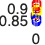

SPLS: itr: 35    diff: 9.17e-06    dim_M1: 5    dim_M2: 20    dim_M3: 10    


matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

% Run generalized SPLS
[weights, covariances,success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 1);